# 分布の描画

clear all; clf;

## データの準備

### 乱数をデータとして用いる

Q1. 0 から 1までの一様乱数を10000個出力し、変数 data1 に格納せよ。

data1 = rand([1 10000])

data1 =     0.7535    0.3061    0.6100    0.0252    0.9210    0.3639    0.2046    0.9237    0.6885    0.3491    0.6090    0.3770    0.7424    0.8586    0.7094    0.3512    0.3971    0.7040    0.3604    0.3317    0.2857    0.5921    0.3313    0.1352    0.5703    0.4239    0.2575    0.8432    0.1082    0.0635    0.9026    0.9468    0.9007    0.9699    0.8076    0.5401    0.8649    0.2623    0.1073    0.1535    0.6552    0.5806    0.0187    0.2117    0.1978    0.8053    0.9440    0.8612    0.1951    0.0198


Q2. 標準正規分布に従う乱数を10000個出力し、変数 data2 に格納せよ。

data2 = randn([1 10000])

data2 =    -0.6674   -1.4147    1.2482   -1.6491   -0.3845    1.7787    0.7014    0.2695    0.3043    0.5136    1.4421    1.1588   -0.2309    0.0974    0.9613    0.7140    0.9732    1.3862    0.1059    0.2637   -1.0376    0.8016    0.7602   -0.0545   -1.0195   -0.2869   -0.8702   -0.4151    0.6564   -1.1696   -0.6606    1.0427   -0.4753   -0.1710    1.7142    0.3508    1.6400   -0.2574   -0.3861   -0.5757   -0.3027    0.7437   -1.1415    0.4330    1.0980    1.6986   -0.2334    0.3705   -0.4694    0.9165


Q3. 平均値 1 の指数分布に従う乱数を10000個出力し、変数 data3 に格納せよ。

pd = makedist('Exponential');
data3 = random(pd, [1 10000])

data3 =     1.4862    0.1182    0.6144    0.4213    0.3898    1.1540    0.8861    0.6916    1.2692    0.4164    0.5700    0.0601    0.1466    0.1412    0.1818    1.3030    1.5618    1.8862    0.0571    0.9117    2.2870    1.5119    1.3935    0.7417    0.4179    0.8797    2.5122    0.7888    3.0512    1.5331    0.6336    0.0384    0.9105    0.4318    0.3736    0.3785    0.7459    1.2523    0.4137    1.7682    0.8661    0.1063    0.7473    0.4576    0.9878    0.6070    1.1524    0.0060    0.7265    0.5921


## 度数分布の描画

Q4. data1 の度数分布を描画せよ。

h1 = histogram(data1)

h1 =   Histogram のプロパティ:

             Data: [0.7535 0.3061 0.6100 0.0252 0.9210 0.3639 0.2046 0.9237 0.6885 0.3491 0.6090 0.3770 0.7424 0.8586 0.7094 0.3512 0.3971 0.7040 0.3604 0.3317 0.2857 0.5921 0.3313 0.1352 0.5703 0.4239 0.2575 0.8432 0.1082 0.0635 0.9026 0.9468 0.9007 … ]
           Values: [499 483 516 482 489 464 531 503 523 460 470 519 493 516 539 511 496 515 514 477]
          NumBins: 20
         BinEdges: [0 0.0500 0.1000 0.1500 0.2000 0.2500 0.3000 0.3500 0.4000 0.4500 0.5000 0.5500 0.6000 0.6500 0.7000 0.7500 0.8000 0.8500 0.9000 0.9500 1]
         BinWidth: 0.0500
        BinLimits: [0 1]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  すべてのプロパティ を

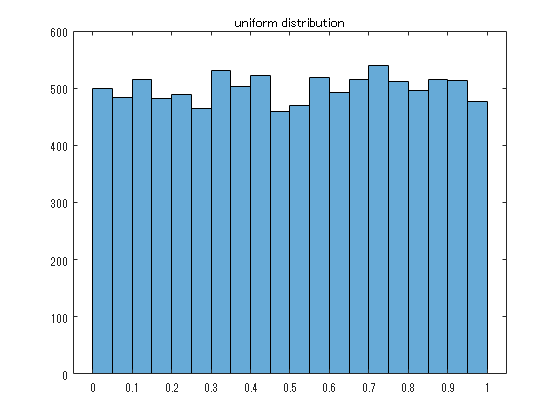

title('uniform distribution')

Q5. data2 の度数分布を描画せよ。

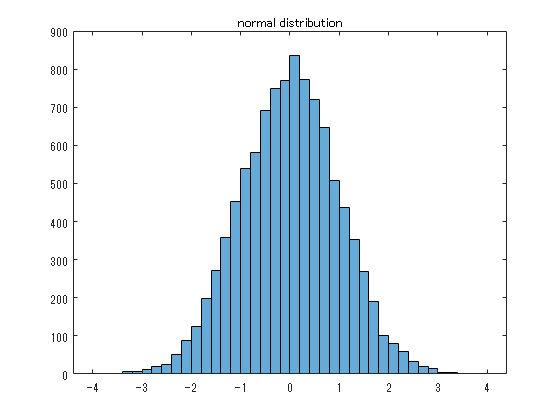

h2 = histogram(data2);
title('normal distribution')

d2 = h2.Values;
x2 = h2.BinEdges(1:end-1)+0.5*h2.BinWidth;


%% 近似: '新規近似 1'。
[xData, yData] = prepareCurveData( x2, d2 );

% 近似タイプとオプションを設定します。
ft = fittype( 'gauss1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.Lower = [-Inf -Inf 0];
opts.StartPoint = [120 11 2.4910787756085];

% モデルをデータに近似します。
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      一般モデル Gauss1:
     fitresult(x) =  a1*exp(-((x-b1)/c1)^2)
     係数 (95% の信頼限界):
       a1 =       798.7  (786.3, 811.1)
       b1 =    0.006438  (-0.01149, 0.02436)
       c1 =       1.416  (1.39, 1.441)

gof = フィールドをもつ struct :
           sse: 8.1766e+03
       rsquare: 0.9974
           dfe: 37
    adjrsquare: 0.9973
          rmse: 14.8657


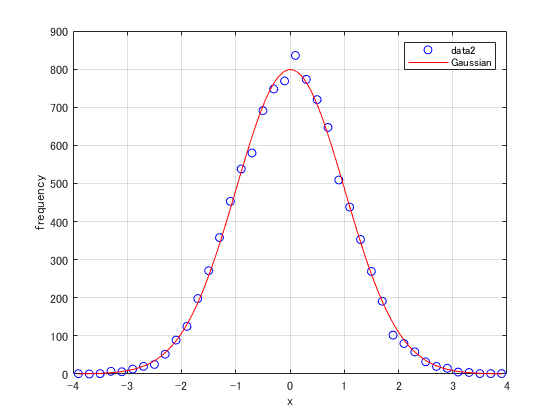


% データの近似をプロットします。
figure( 'Name', '新規近似 1' );
h = plot( fitresult, xData, yData, 'bo' );
legend( h, 'data2', 'Gaussian', 'Location', 'NorthEast', 'Interpreter', 'none' );
% ラベル Axes
ylabel( 'frequency', 'Interpreter', 'none' );
grid on

Q6. data3 の度数分布を描画せよ。

h3 = histogram(data3)

h3 =   Histogram のプロパティ:

             Data: [1.4862 0.1182 0.6144 0.4213 0.3898 1.1540 0.8861 0.6916 1.2692 0.4164 0.5700 0.0601 0.1466 0.1412 0.1818 1.3030 1.5618 1.8862 0.0571 0.9117 2.2870 1.5119 1.3935 0.7417 0.4179 0.8797 2.5122 0.7888 3.0512 1.5331 0.6336 0.0384 0.9105 … ]
           Values: [1873 1492 1218 943 806 722 556 437 345 319 247 205 140 127 104 74 70 46 52 49 40 20 27 16 12 10 13 4 6 4 6 3 3 1 3 0 1 0 1 1 0 1 1 1 0 0 0 0 0 1]
          NumBins: 50
         BinEdges: [0 0.2000 0.4000 0.6000 0.8000 1 1.2000 1.4000 1.6000 1.8000 2 2.2000 2.4000 2.6000 2.8000 3 3.2000 3.4000 3.6000 3.8000 4 4.2000 4.4000 4.6000 4.8000 5 5.2000 5.4000 5.6000 5.8000 6 6.2000 6.4000 6.6000 6.8000 7 7.2000 7.4000 … ]
         BinWidth: 0.2000
        BinLimits: [0 10]
    Normalization: 'count'
        FaceColor: 'auto'
        EdgeColor: [0 0 0]

  

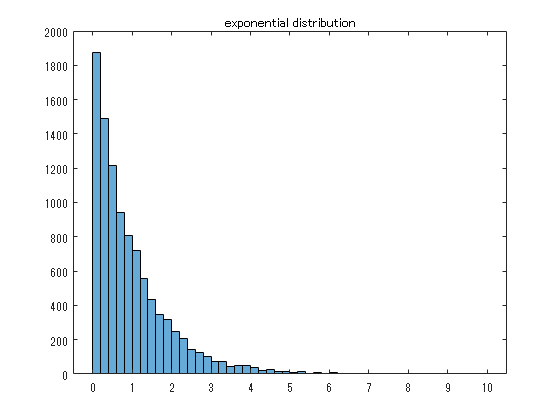

title('exponential distribution')

d3 = h3.Values;
x3 = h3.BinEdges(1:end-1)+0.5*h3.BinWidth;


%% 近似: '新規近似 1'。
[xData, yData] = prepareCurveData( x3, d3 );

% 近似タイプとオプションを設定します。
ft = fittype( 'exp1' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [358.381349383821 -0.306273949241911];

% モデルをデータに近似します。
[fitresult, gof] = fit( xData, yData, ft, opts )

fitresult =      一般モデル Exp1:
     fitresult(x) = a*exp(b*x)
     係数 (95% の信頼限界):
       a =        2045  (2019, 2072)
       b =      -1.022  (-1.041, -1.004)

gof = フィールドをもつ struct :
           sse: 9.8538e+03
       rsquare: 0.9988
           dfe: 48
    adjrsquare: 0.9988
          rmse: 14.3279


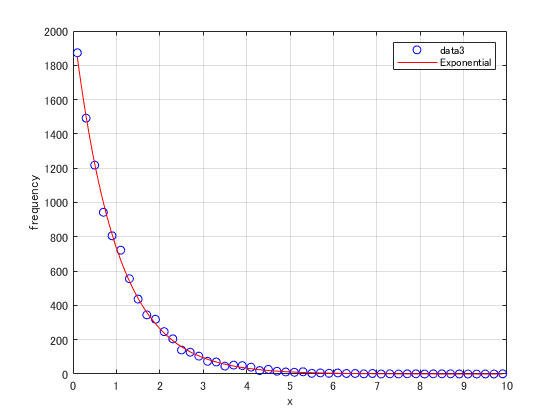


% データの近似をプロットします。
figure( 'Name', '新規近似 1' );
h = plot( fitresult, xData, yData, 'bo' );
legend( h, 'data3', 'Exponential', 'Location', 'NorthEast', 'Interpreter', 'none' );
% ラベル Axes
ylabel( 'frequency', 'Interpreter', 'none' );
grid on

## 演習

Q1. $-1$ から $+1$までの一様乱数を1000個出力し、それらの度数分布を描画せよ。

Q2. 平均 $2$、標準偏差 $3$ の正規分布に従う乱数を1000個出力し、それらの度数分布を描画せよ。

Q3.  平均 10 のポアソン分布に従う乱数を1000個出力し、それらの度数分布を描画せよ。

## 参考文献

- [https://jp.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html](https://jp.mathworks.com/help/matlab/ref/matlab.graphics.chart.primitive.histogram.html)

- [https://jp.mathworks.com/help/stats/prob.normaldistribution.random.html](https://jp.mathworks.com/help/stats/prob.normaldistribution.random.html)